clear;

A = [25 6 -20 11;
    14 3 -10 4;
    40 11 -31 17;
    6 4 -4 3];

C = [1 0 -1 1];
x0 = [1; 1; 1; 1];
xh0 = [0; 0; 0; 0];

%L = [1; 1; 1; 1];



%{
t = 0:0.0001:2;
f = [ 0.5*sin(2*pi*0.1*t);
    0.3*cos(2*pi*0.2*t);
    0.4*sin(2*pi*0.15*t + pi/4);
    0.2*cos(2*pi*0.05*t)];

xi = 0.1*sin(2*pi*0.3*t) + 0.05*cos(2*pi*0.25*t);
%}
%============================================================
nu = 1;
%Q = eye(4);
%R = 1;
Q = diag([0.125, 0.045, 0.08, 0.02]);  % Для f(t)
R = 0.00625;  
alpha = 10;
aQ = alpha * Q;
aR = alpha * R;
%===================L1======================================
[P1,~,K] = icare(A', C', Q, R, [], [], [], nu);

disp("Determinant of P1");

Determinant of P1


disp(det(P1));

    0.0044




disp("P1");

P1


disp(P1);

    4.4989    2.7770    8.5620    4.3264
    2.7770    1.7850    5.3296    2.7011
    8.5620    5.3296   16.7744    8.8389
    4.3264    2.7011    8.8389    4.9640




L1 = -P1* C' * inv(R);
disp("L1");

L1


disp(L1);

  -42.1376
  -23.7574
 -100.2404
  -72.2422




%=================L2========================================
[P2,~,K] = icare(A', C', aQ, R, [], [], [], nu);

disp("Determinant of P2");

Determinant of P2


disp(det(P2));

    4.3530




disp("P2");

P2


disp(P2);

   36.8687   22.7499   67.2704   31.2469
   22.7499   14.4418   41.9228   19.6924
   67.2704   41.9228  125.7265   60.3284
   31.2469   19.6924   60.3284   30.2851




L2 = -P2* C' * inv(R);
disp("L2");

L2


disp(L2);

 -135.2327
  -83.1196
 -299.5609
 -192.5766




%====================L3=====================================
[P3,~,K] = icare(A', C', Q, aR, [], [], [], nu);

disp("Determinant of P3");

Determinant of P3


disp(det(P3));

    0.1771




disp("P3");

P3


disp(P3);

    5.9417    3.5484   12.0317    6.8415
    3.5484    2.4879    7.2427    3.9862
   12.0317    7.2427   25.5346   15.5645
    6.8415    3.9862   15.5645   10.5382




L3 = -P3* C' * inv(aR);
disp("L3");

L3


disp(L3);

  -12.0240
   -4.6699
  -32.9840
  -29.0436




%====================L4=====================================
[P4,~,K] = icare(A', C', aQ, aR, [], [], [], nu);

disp("Determinant of P4");

Determinant of P4


disp(det(P4));

   43.6826




disp("P4");

P4


disp(P4);

   44.9895   27.7699   85.6200   43.2641
   27.7699   17.8499   53.2958   27.0108
   85.6200   53.2958  167.7439   88.3890
   43.2641   27.0108   88.3890   49.6400




L4 = -P4* C' * inv(aR);
disp("L4");

L4


disp(L4);

  -42.1376
  -23.7574
 -100.2404
  -72.2422



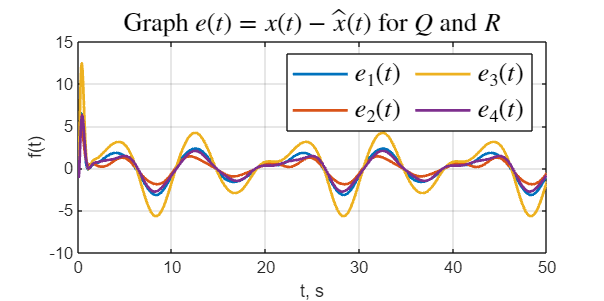


%===========Modeling==================================


L=L1;

open_system('task_2_simm');
set_param('task_2_simm/x', 'VariableName', 'x')
set_param('task_2_simm/xh', 'VariableName', 'xh')
set_param('task_2_simm/e', 'VariableName', 'e')

out = sim('task_2_simm');

figure('Position', [100 100 800 400])
plot(out.e,'-', 'LineWidth',1.5);
%hold on
%plot(out.xh,'--', 'LineWidth',1.5);

grid()
title('Graph $e(t) = x(t) - \hat{x}(t)$ for $Q$ and $R$','Interpreter','latex',  'FontSize', 14)
legend('$e_1(t)$', '$e_2(t)$', '$e_3(t)$', '$e_4(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')

%hold off

%{
figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5);
hold on
plot(out.xh,'--', 'LineWidth',1.5);

grid()
title('Graph $x(t)$ and $\hat{x}(t)$ for $\alpha Q$ and $\alpha R$','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$x_2(t)$', '$x_3(t)$', '$x_4(t)$', ...
    '$\hat{x}_1(t)$', '$\hat{x}_2(t)$', '$\hat{x}_3(t)$', '$\hat{x}_4(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
hold off
%}
